## Uneccecary!

## FFT idea

time_FFT = tic ;

z_k_signal_1 = h1;
z_k_signal_2 = h2;

N=length(h1);
N_half=N/2;


$$$\vec{f^e} = \left[\matrix{f_0 \cr f_2 \cr f_4 \cr \vdots} \right] \in \mathbb{R}^{n/2}$
$$
  
$$$\vec{f^o} = \left[\matrix{f_1 \cr f_3 \cr f_5 \cr \vdots} \right] \in \mathbb{R}^{n/2}$$$


h1_even = z_k_signal_1(1:2:end);
h1_odd = z_k_signal_1(2:2:end);

h2_even = z_k_signal_2(1:2:end);
h2_odd = z_k_signal_2(2:2:end);

#### Calculation of two DFTs

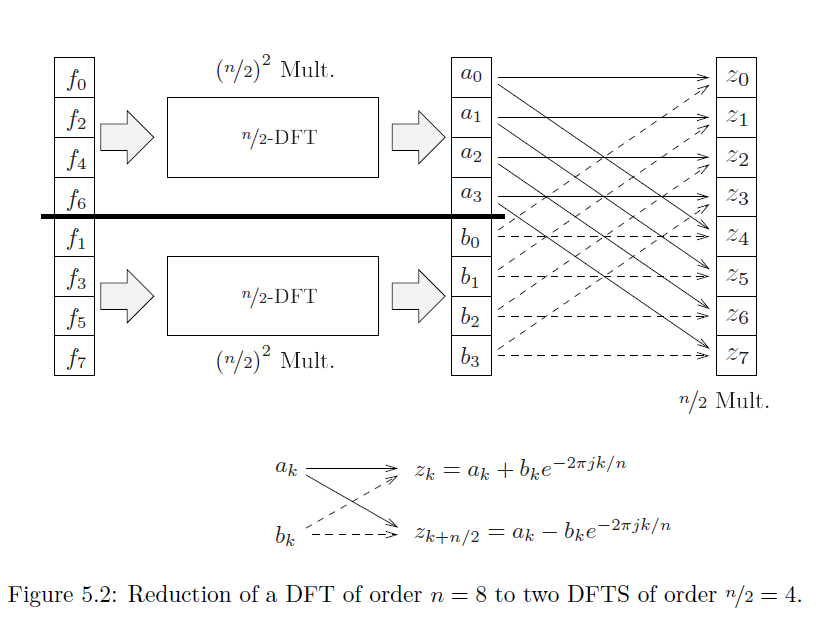


$$a_k = \sum_{\ell=0}^{n/2 - 1} f_{\ell}^e e^{-2 \pi j k \ell / (n/2)} $$
 
$$b_k = \sum_{\ell=0}^{n/2 - 1} f_{\ell}^o e^{-2 \pi j k \ell / (n/2)}$$


a_k_signal_1 = zeros(1, N_half);
b_k_signal_1 = zeros(1, N_half);

a_k_signal_2 = zeros(1, N_half);
b_k_signal_2 = zeros(1, N_half);

FFT_idea_factor = zeros(N_half, N_half);
FFT_it_factor_zk = zeros(1,N_half);
FFT_idea_factor_zk = zeros(1,N_half);
for k = 1:N_half
    FFT_idea_factor_zk(k) = exp(-2 * pi * 1i * k / N);
    for l = 1:N_half
        FFT_idea_factor(k,l) = exp(-2 * pi * 1i * k*l/ N_half);
    end
end

for k = 1:N_half
    for l = 1:N_half
        a_k_signal_1(k) = a_k_signal_1(k) + h1_even(l) * FFT_idea_factor(k,l); %exp(-2 * pi * 1i * k*l/ N_half);
        b_k_signal_1(k) = b_k_signal_1(k) + h1_odd(l) * FFT_idea_factor(k,l); %exp(-2 * pi * 1i * k*l/ N_half);

        a_k_signal_2(k) = a_k_signal_2(k) + h2_even(l) * FFT_idea_factor(k,l); %exp(-2 * pi * 1i * k*l/ N_half);
        b_k_signal_2(k) = b_k_signal_2(k) + h2_odd(l) * FFT_idea_factor(k,l); %exp(-2 * pi * 1i * k*l/ N_half);
    end
end

#### Combination of both DFTs


$$z_{k + n/2} = a_k - b_k e^{-2 \pi j k / n}$$


z_k_new_signal_1 = zeros(1, N_half);
z_k_new_signal_2 = zeros(1, N_half);

for k = 1:N_half
    %factor = exp(-2 * pi * 1i * k / N);
    z_k_new_signal_1(k) = a_k_signal_1(k) + b_k_signal_1(k) * FFT_idea_factor_zk(k); %factor;
    z_k_new_signal_1(k + N_half) = a_k_signal_1(k) - b_k_signal_1(k) * FFT_idea_factor_zk(k); %factor;

    z_k_new_signal_2(k) = a_k_signal_2(k) + b_k_signal_2(k) * FFT_idea_factor_zk(k); %factor;
    z_k_new_signal_2(k + N_half) = a_k_signal_2(k) - b_k_signal_2(k) * FFT_idea_factor_zk(k); %factor;
end

FFT_idea_signal_1 = z_k_new_signal_1;
FFT_idea_signal_2 = z_k_new_signal_2;

time_FFT = toc(time_FFT)

#### Cyclic shift


$$ F_k e^{-2 \pi j k \frac{m}{n}}$$


cyclic shift by m places

shifted_FFT_idea_signal_1 = [FFT_idea_signal_1(N_half:end), FFT_idea_signal_1(1:N_half-1)];
shifted_FFT_idea_signal_2 = [FFT_idea_signal_2(N_half:end), FFT_idea_signal_2(1:N_half-1)];

% Amplitudespectrum
shifted_FFT_idea_signal_1_magnitude = abs(shifted_FFT_idea_signal_1);
shifted_FFT_idea_signal_2_magnitude = abs(shifted_FFT_idea_signal_2);

% Frequency axis
k_raw=1:N;                                              % Formelsammlung
f_raw=(k_raw-1)*(1/(N*ts));                             % Formelsammlung
f_c_raw=f_raw-((N-mod(N,2))/2)*(1/(N*ts));              % Formelsammlung

#### Plot

figure;
tiledlayout(2,1)
nexttile
plot(f_c_raw, 1/N*shifted_FFT_idea_signal_1_magnitude);
hold on
plot(f_c_raw,shifted_DFT_signal_1_magnitude*0.9)
plot(f_c_raw,1/N*abs(fftshift((FFT_signal_1_raw)))*0.8)
xline(-cutoff_f,LineStyle="--",Color='red',Label='Cutoff frequency')
xline(cutoff_f,LineStyle="--",Color='red',Label='Cutoff frequency')
hold off
title('Frequenzspektrum des Signals 1');
xlabel('Frequenz (Hz)');
ylabel('Amplitude');
legend('FFT iterativ','DFT matrix','Matlab')
nexttile
plot(f_c_raw, 1/N*shifted_FFT_idea_signal_2_magnitude);
hold on
plot(f_c_raw,shifted_DFT_signal_2_magnitude*0.9)
plot(f_c_raw,1/N*abs(fftshift((FFT_signal_2_raw)))*0.8)
xline(-cutoff_f,LineStyle="--",Color='red',Label='Cutoff frequency')
xline(cutoff_f,LineStyle="--",Color='red',Label='Cutoff frequency')
hold off
title('Frequenzspektrum des Signals 2');
xlabel('Frequenz (Hz)');
ylabel('Amplitude');
legend('FFT iterativ','DFT matrix','Matlab')